Normalized far field patterns of the circular antenna feed at the two main cuts (E- and H- planes) in dB.

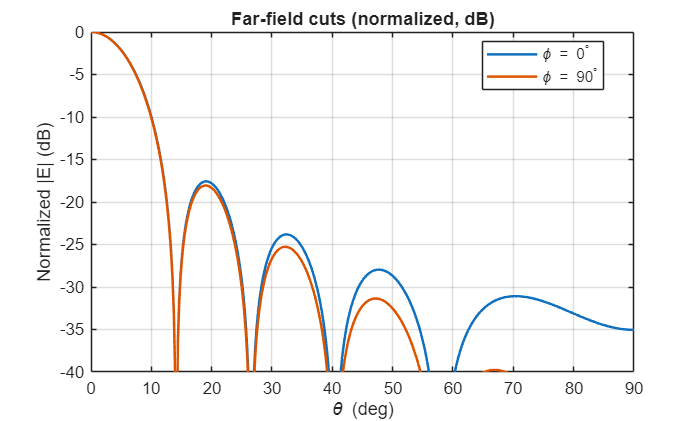

% Constants
f = 300e9;
c0 = 3e8;
lambda_0 = c0 / f;
k0 = 2*pi / lambda_0;

zeta0 = 120*pi;

D_f  = 5 * lambda_0;
a    = D_f / 2;
J_f  = 1;

% Angular grid
num_th = 401;
theta_feed = linspace(eps, pi / 2,  num_th);
phi_feed   = [eps pi/2];
[TH_feed, PH_feed] = meshgrid(theta_feed, phi_feed);

% Feed distance 
r_feed = 1; 
r_feed = r_feed .* ones(size(TH_feed));

% J_FT 
x = k0*a*sin(TH_feed);
J_FT = 2*pi*a^2 .* besselj(1, x) ./ x;  

% Common prefactor
pref = (-2*1j*k0*zeta0*J_f) .* abs(J_FT) .* exp(-1j*k0*r_feed) ./ (4*pi*r_feed);

% Spherical components 
E_theta = pref .* (cos(TH_feed) .* sin(PH_feed));
E_phi   = pref .* (cos(PH_feed));

E_ff = zeros([size(TH_feed), 3]);
E_ff(:,:,1) = 0;        
E_ff(:,:,2) = E_theta; 
E_ff(:,:,3) = E_phi;    

H_theta = -(1/zeta0) * E_phi;
H_phi   =  (1/zeta0) * E_theta;

H_ff = zeros(size(E_ff));    
H_ff(:,:,1) = 0;             
H_ff(:,:,2) = H_theta;        
H_ff(:,:,3) = H_phi;          

% --- Far-field magnitude (total E) on the grid
E_mag = sqrt(abs(E_theta).^2 + abs(E_phi).^2);   % 2 × num_th

% Indices for cuts: phi_feed = [~0, pi/2]
idx_phi0  = 1;   % phi ≈ 0
idx_phi90 = 2;   % phi = pi/2

E0  = E_mag(idx_phi0 , :);
E90 = E_mag(idx_phi90, :);

% Normalize to the peak across BOTH cuts (common normalization)
Emax = max([E0(:); E90(:)]);
E0n  = E0  / Emax;
E90n = E90 / Emax;

% dB (protect against log(0))
floor_lin = 1e-12;
E0_dB  = 20*log10(max(E0n , floor_lin));
E90_dB = 20*log10(max(E90n, floor_lin));

figure;
plot(theta_feed*180/pi, E0_dB,  'LineWidth', 1.5); hold on;
plot(theta_feed*180/pi, E90_dB, 'LineWidth', 1.5);
grid on;
xlabel('\theta (deg)');
ylabel('Normalized |E| (dB)');
ylim([-40 0]); % adjust
xlim([0 90]);
legend('\phi = 0^\circ', '\phi = 90^\circ', 'Location', 'best');
title('Far-field cuts (normalized, dB)');

Now we are going to plot uv plot:

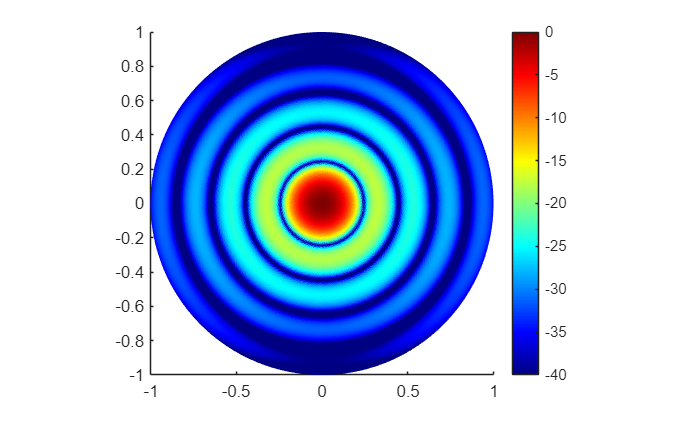

% Constants
f = 300e9;
c0 = 3e8;
lambda_0 = c0 / f;
k0 = 2*pi / lambda_0;

zeta0 = 120*pi;

D_f  = 5 * lambda_0;
a    = D_f / 2;
J_f  = 1;

% Angular grid
num_th = 401;
num_ph = 401;
theta_feed = linspace(eps, pi,  num_th);
phi_feed   = linspace(eps, 2*pi,  num_th);
[TH_feed, PH_feed] = meshgrid(theta_feed, phi_feed);

% Feed distance 
r_feed = 1; 
r_feed = r_feed .* ones(size(TH_feed));

% J_FT 
x = k0*a*sin(TH_feed);
J_FT = 2*pi*a^2 .* besselj(1, x) ./ x;  

% Common prefactor
pref = (-2*1j*k0*zeta0*J_f) .* abs(J_FT) .* exp(-1j*k0*r_feed) ./ (4*pi*r_feed);

% Spherical components 
E_theta = pref .* (cos(TH_feed) .* sin(PH_feed));
E_phi   = pref .* (cos(PH_feed));

E_ff = zeros([size(TH_feed), 3]);
E_ff(:,:,1) = 0;        
E_ff(:,:,2) = E_theta; 
E_ff(:,:,3) = E_phi;    

% --- Far-field magnitude (total E) on the grid
E_mag = sqrt(abs(E_theta).^2 + abs(E_phi).^2);   

E_ff_norm = E_mag ./ max(E_mag(:));
E_ff_dB_norm = 20*log10(max(E_ff_norm, floor_lin));

X = sin(TH_feed).*cos(PH_feed);
Y = sin(TH_feed).*sin(PH_feed);

figure;
surface(X, Y, E_ff_dB_norm, 'LineStyle','none');  % required line
colormap(jet);
view(2);
colorbar;
clim([-40 0]);
axis equal;
axis([-1 1 -1 1]);                                % required line

1a. Spill over efficiency

D = 4;
f_focus = 3;
f_hash = f_focus / D;
th0 = 2 * acot(4 * f_hash);

% Constants
f = 300e9;
c0 = 3e8;
lambda_0 = c0 / f;
k0 = 2*pi / lambda_0;

zeta0 = 120*pi;

D_f  = 5*lambda_0;
a    = D_f / 2;
J_f  = 1;

% Angular grid
num_th = 401;
num_ph = 401;
theta_feed = linspace(eps, pi/2,  num_th);
phi_feed   = linspace(eps, 2*pi,  num_ph);
[TH_feed, PH_feed] = meshgrid(theta_feed, phi_feed);

% Feed distance 
r_feed = 1; 
r_feed = r_feed .* ones(size(TH_feed));

% J_FT 
x = k0*a*sin(TH_feed);
J_FT = 2*pi*a^2 .* besselj(1, x) ./ x;  

% Common prefactor
pref = (-2*1j*k0*zeta0*J_f) .* J_FT .* exp(-1j*k0*r_feed) ./ (4*pi*r_feed);

% Spherical components 
E_theta = pref .* (cos(TH_feed) .* sin(PH_feed));
E_phi   = pref .* (cos(PH_feed));

E_ff = zeros([size(TH_feed), 3]);
E_ff(:,:,1) = 0;        
E_ff(:,:,2) = E_theta; 
E_ff(:,:,3) = E_phi;    

E_mag = sqrt(abs(E_theta).^2 + abs(E_phi).^2);   
U_feed = 1 / (2 * zeta0) .* abs(E_mag) .^2 .* r_feed .^ 2 .* sin(TH_feed);

INTERGRAND_lim = U_feed;
INTERGRAND_lim(TH_feed>th0) = 0;

dth_feed = (pi/2)/(num_th-1);
dph_feed = (2*pi)/(num_ph-1);


ita = (sum(sum(INTERGRAND_lim))*dth_feed*dph_feed) / (sum(sum(U_feed))*dth_feed*dph_feed)

ita = 0.9638

Current on Equivalent Aperture

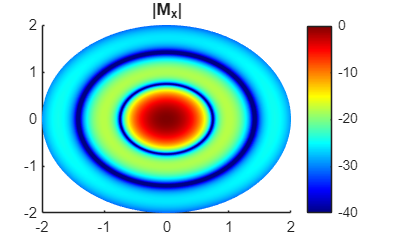

D = 4;
f_focus = 3;
f_hash = f_focus / D;
th0 = 2 * acot(4 * f_hash);

% Constants
f = 300e9;
c0 = 3e8;
lambda_0 = c0 / f;
k0 = 2*pi / lambda_0;
k = k0;

zeta0 = 120*pi;

D_f  = 5*lambda_0;
a    = D_f / 2;
J_f  = 1;

% Angular grid
num_th = 401;
num_ph = 401;
theta_feed = linspace(eps, th0,  num_th); % Only use wave that will be reflected.
phi_feed   = linspace(eps, 2*pi,  num_ph);
[TH_feed, PH_feed] = meshgrid(theta_feed, phi_feed);

% Feed distance 
r_feed = 1; 
r_feed = r_feed .* ones(size(TH_feed));

% J_FT 
x = k0*a*sin(TH_feed);
J_FT = 2*pi*a^2 .* besselj(1, x) ./ x;  

% Common prefactor
pref = (-2*1j*k0*zeta0*J_f) .* J_FT .* exp(-1j*k0*r_feed) ./ (4*pi*r_feed);

% Spherical components 
E_theta = pref .* (cos(TH_feed) .* sin(PH_feed));
E_phi   = pref .* (cos(PH_feed));


RHO_p = 2 .* f_focus .* tan(TH_feed ./ 2);
PH_p = PH_feed;

Ea_rho = -E_theta .* exp(-1j*k*2*f_focus).*cos(TH_feed/2).^2/f_focus;
Ea_phi = -E_phi .* exp(-1j*k*2*f_focus).*cos(TH_feed/2).^2/f_focus;

Ea_x = Ea_rho.*cos(PH_p) - Ea_phi.*sin(PH_p);
Ea_y = Ea_rho.*sin(PH_p) + Ea_phi.*cos(PH_p);

E_a = zeros([size(Ea_x), 3]);
E_a(:, :, 1) = Ea_x;
E_a(:, :, 2) = Ea_y;

n = zeros([size(TH_feed), 3]); 
n(:,:,3) = ones(size(TH_feed));
M = cross(E_a, n, 3);
M_x = M(:, :, 1);
M_y = M(:, :, 2);

M = sqrt(abs(M(:, :, 1)).^2 + abs(M(:, :, 2)).^2 + abs(M(:, :, 3)).^2);

U = RHO_p.*cos(PH_p);
V = RHO_p.*sin(PH_p);

figure
hold on
surface(U, V, 20*log10(abs(M_x))-max(max(20*log10(abs(M_x)))) , 'linestyle' , 'none' ) ;
title("|M_x|")
colormap("jet")
colorbar
clim([-40 0])
axis([ -2 2 -2 2])

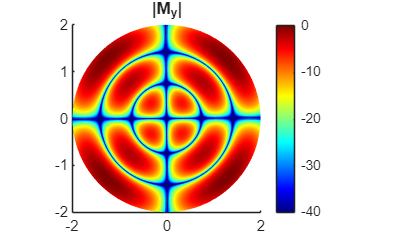


figure
hold on
surface(U, V, 20*log10(abs(M_y)) - max(max(20*log10(abs(M_y)))) , 'linestyle' , 'none' ) ;
axis equal
axis([ -2 2 -2 2])
title("|M_y|")
colormap("jet")
colorbar
clim([-40 0])

Taper efficiency

drho = abs(RHO_p(1, 1) - RHO_p(1, 2));
dphi = abs(PH_p(1, 1) - PH_p(2,1));

rho_prime = RHO_p;
phi_prime = PH_p;

int_x = sum(sum(E_a(:,:,1) .* rho_prime)) * drho * dphi;
int_y = sum(sum(E_a(:,:,2) .* rho_prime)) * drho * dphi;
int_z = sum(sum(E_a(:,:,3) .* rho_prime)) * drho * dphi;

numerator_sq = abs(int_x + int_y + int_z)^2;

% Denominator: integral of |E|^2 * rho'
integrand_den = (abs(E_a(:,:,1)).^2 + abs(E_a(:,:,2)).^2 + abs(E_a(:,:,3)).^2);
denominator = sum(sum(integrand_den .* rho_prime)) * drho * dphi;

% Taper efficiency
A = pi * (D/2)^2;
eta_taper = (1/A) * numerator_sq / denominator

eta_taper = 0.0577

Far field after reflector

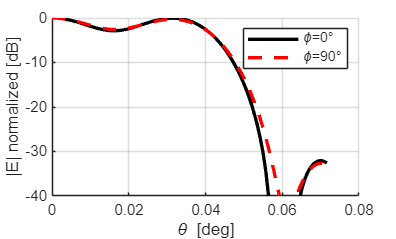

%%
% Surface current (PMC image: factor 2)
J_s = 1/zeta0 * cross(n, cross(n, E_a, 3), 3);
Js_x = 2 * squeeze(J_s(:,:,1));
Js_y = 2 * squeeze(J_s(:,:,2));

% Far field grid
% ph_ff = linspace(eps, 2*pi-eps, 100);
ph_ff = [0 pi/2];
th_ff = linspace(0, 5*lambda_0/D, 100);


% Pre-allocate
Eth = zeros(length(ph_ff), length(th_ff));
Eph = zeros(length(ph_ff), length(th_ff));

R_ff = 1;

for ii = 1:length(th_ff)
    for jj = 1:length(ph_ff)
        
        % Current observation point
        th  = th_ff(ii);
        ph  = ph_ff(jj);
        
        kx = k*sin(th)*cos(ph);
        ky = k*sin(th)*sin(ph);
        kz = k*cos(th);
        
        % Phase term over aperture [N_ap_phi x N_ap_rho]
        phase = exp(1j*(kx*rho_prime.*cos(phi_prime) + ky*rho_prime.*sin(phi_prime)));
        
        % Integrate over aperture
        JFT_x = sum(sum(Js_x .* phase .* rho_prime)) * drho * dphi;
        JFT_y = sum(sum(Js_y .* phase .* rho_prime)) * drho * dphi;
        
        % Green's function (scalar kx, ky for this observation point)
        GF = EJ_SGF(zeta0, k, kx, ky);
        Gxx = GF(:,:,1,1); Gyx = GF(:,:,2,1); Gzx = GF(:,:,3,1);
        Gxy = GF(:,:,1,2); Gyy = GF(:,:,2,2); Gzy = GF(:,:,3,2);
        
        % Far field contributions
        [Eth_x, Eph_x] = farfield(k, R_ff, th, ph, kz, Gxx, Gyx, Gzx, JFT_x);
        [Eth_y, Eph_y] = farfield(k, R_ff, th, ph, kz, Gxy, Gyy, Gzy, JFT_y);
        
        Eth(jj, ii) = Eth_x + Eth_y;
        Eph(jj, ii) = Eph_x + Eph_y;
      
    end
end

% Total field
E_ff = sqrt(abs(Eth).^2 + abs(Eph).^2);
E_ff_max = max(max(20*log10(abs(E_ff))));

[~, idx_phi_0]  = min(abs(ph_ff - 0));
[~, idx_phi_90] = min(abs(ph_ff - pi/2));

figure; hold on; grid on;
plot(rad2deg(th_ff), 20*log10(abs(E_ff(idx_phi_0,:)))  - E_ff_max, '-k', 'LineWidth', 2)
plot(rad2deg(th_ff), 20*log10(abs(E_ff(idx_phi_90,:))) - E_ff_max, '--r', 'LineWidth', 2)
xlabel('\theta [deg]'); ylabel('|E| normalized [dB]')
legend('\phi=0°', '\phi=90°'); ylim([-40 0])